clc, clear
rng('shuffle')
red = [255 0 0];
orange = [255 127 0];
yellow = [255 255 0];
green = [0 255 0];
blue = [0 0 255];
navy = [0 0 128];
purple = [160 32 240];

label = {'red' 'orange' 'yellow' 'green' 'blue' 'navy' 'purple'};
color = {red, orange, yellow, green, blue, navy, purple};

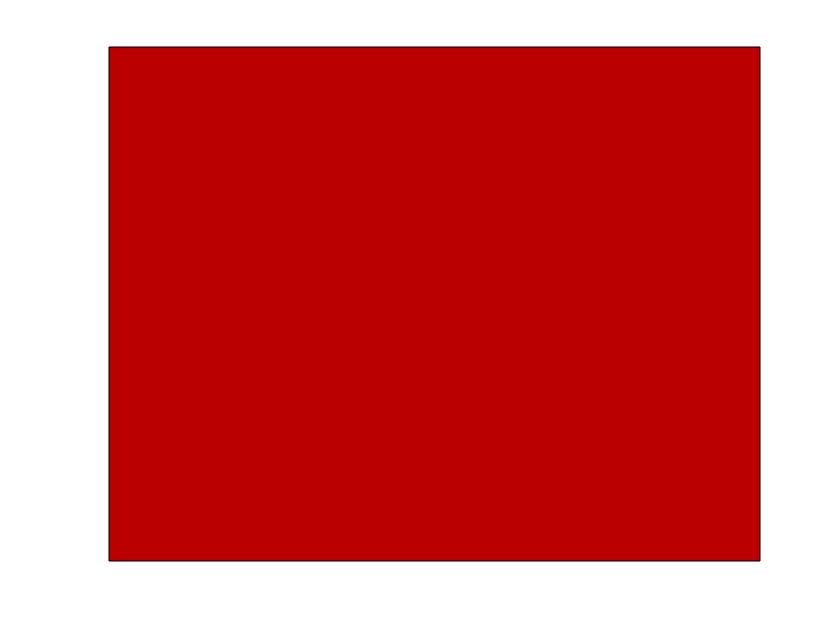

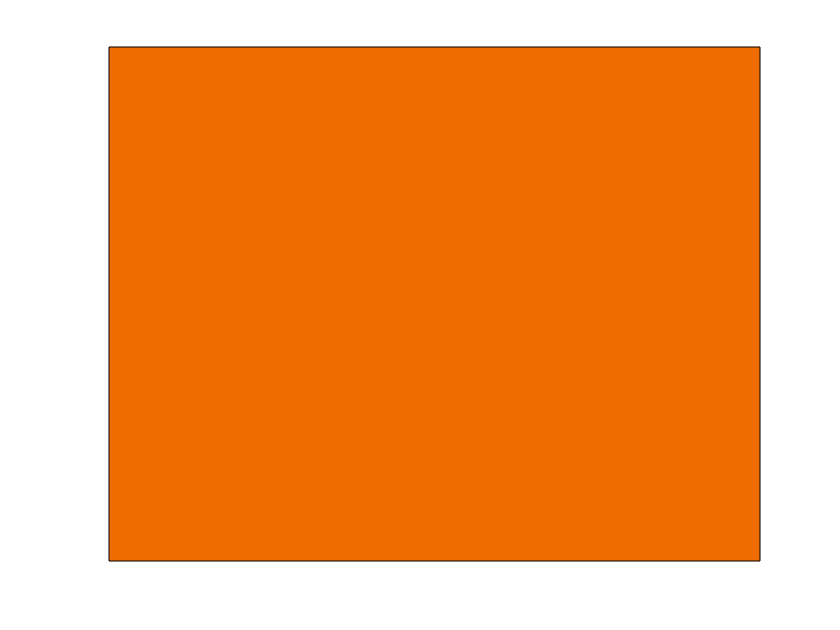

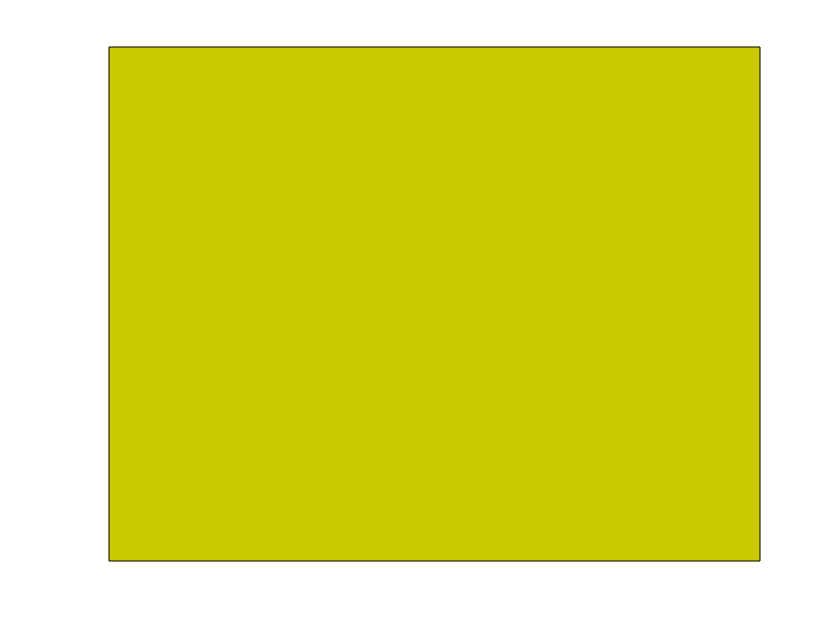

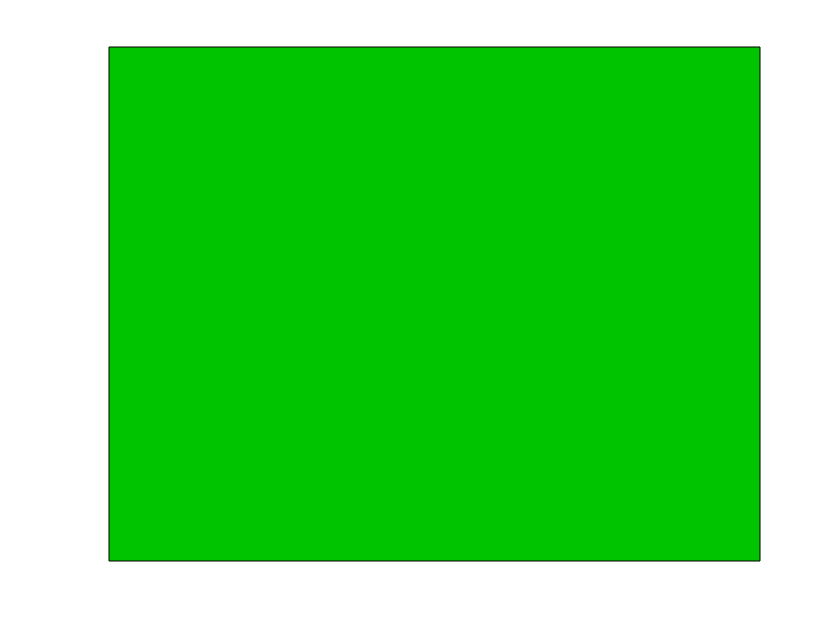

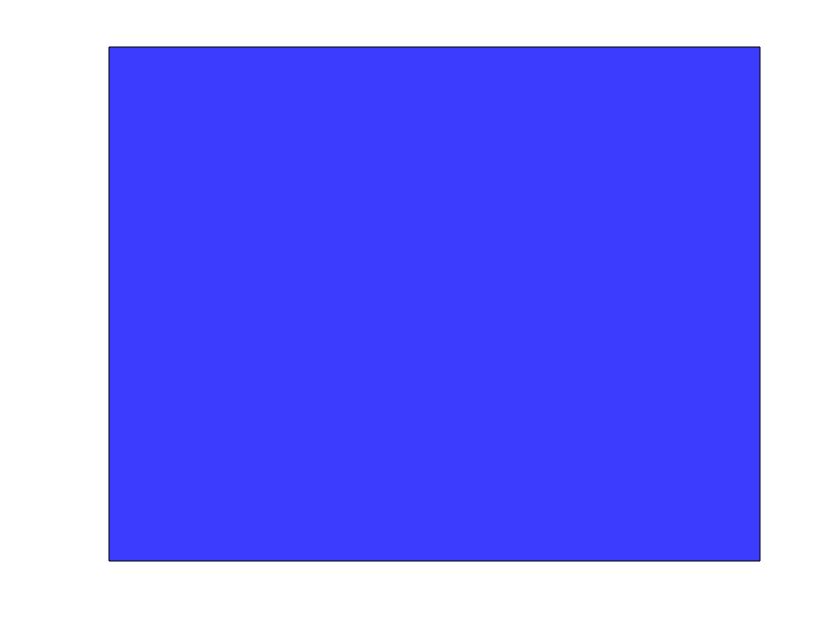

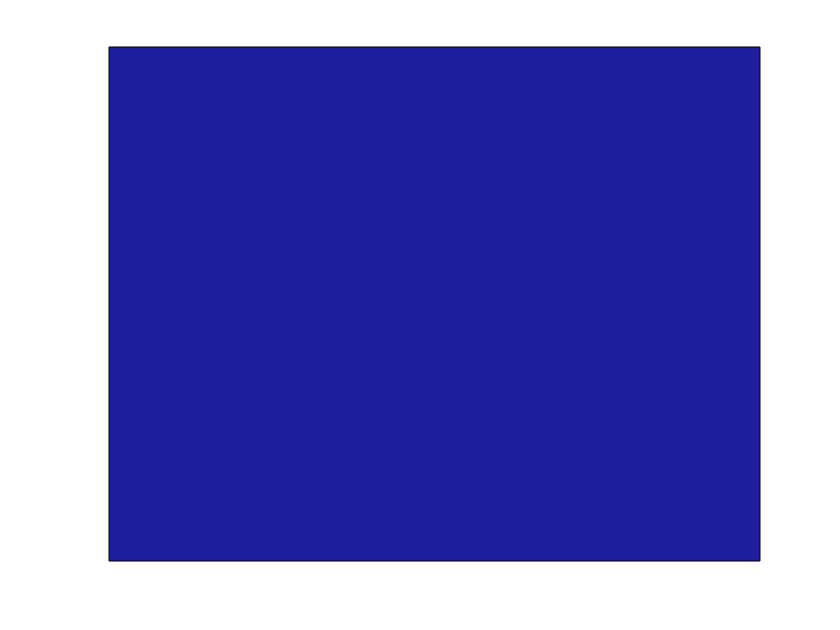

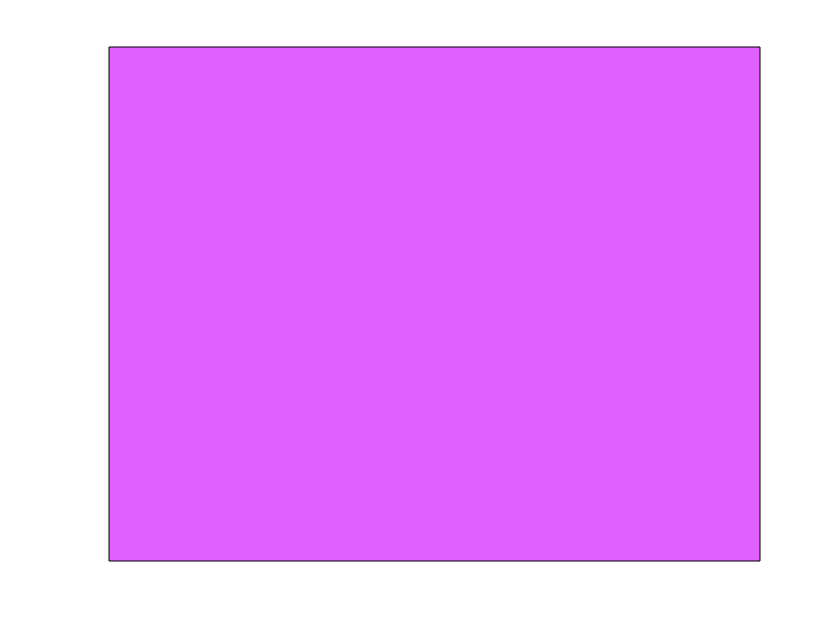

savedir = uigetdir;
for i=1:length(label)
    cd(savedir)
    if isfolder(label{i}) == false
        mkdir(label{i})
    end
    cd(label{i})
    
    for j=1:100
        clearvars temp
        % 80% ~ 100%
        minvalue = floor(255*0.7);
        value = 255 - randi([minvalue 255]);
        
        if rand > 0.5
            %plus
            temp = color{i} + value;
            idx = temp > 255;
            temp(idx) = 255;
        else
            %minus
            temp = color{i} - value;
            idx = temp < 0;
            temp(idx) = 0;
        end
        
        hexStr = dec2hex(temp);
        str = strcat('#', hexStr(1,:), hexStr(2,:), hexStr(3,:));
        figure(i)
        rectangle('Position', [0 0 1 1], 'FaceColor', str);
        xticks([])
        yticks([])
        
        saveas(gcf, strcat(string(j), '.png'));
    end
end

cd(savedir)
cd ../
k = strfind(savedir,'\');
foldername = savedir(k(end)+1:end);
imds = imageDatastore(foldername, "IncludeSubfolders",true,'LabelSource',"foldernames")

imds =   ImageDatastore - 속성 있음:

                       Files: {
                              'C:\Users\An S\Downloads\dataset\dataset\Color\blue\1.png';
                              'C:\Users\An S\Downloads\dataset\dataset\Color\blue\10.png';
                              'C:\Users\An S\Downloads\dataset\dataset\Color\blue\100.png'
                               ... and 697 more
                              }
                     Folders: {
                              'C:\Users\An S\Downloads\dataset\dataset\Color'
                              }
                      Labels: [blue; blue; blue ... and 697 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage



[trds, teds] = splitEachLabel(imds, 0.7);

trLabel = trds.Labels;
teLabel = teds.Labels;

trds = augmentedImageDatastore([30 30], trds);
teds = augmentedImageDatastore([30 30], teds);

layers = [
    imageInputLayer([30 30 3], 'Name', 'ColorImgInput')
    fullyConnectedLayer(10, 'Name', 'Hidden Layer')
    fullyConnectedLayer(7, 'Name', 'OutputLayer')
    softmaxLayer('Name', 'Softmax')
    classificationLayer('Name', 'Classification output')
    ];

opts = trainingOptions('adam', 'InitialLearnRate', 0.001, "Plots","training-progress")

opts =   TrainingOptionsADAM - 속성 있음:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.1000
           LearnRateDropPeriod: 10
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 30
                 MiniBatchSize: 128
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: []
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'training-progress


mynet = trainNetwork(trds, layers, opts);

단일 GPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０６　｜　　　　　　　０．００％　｜　　　　１５．９４２４　｜　　　０．００１０　｜


｜　　　　　　１７　｜　　　　　　５０　｜　　　　　００：００：２３　｜　　　　　　９６．０９％　｜　　　　　０．１６０１　｜　　　０．００１０　｜


｜　　　　　　３０　｜　　　　　　９０　｜　　　　　００：００：３６　｜　　　　　１００．００％　｜　－０．００００ｅ＋００　｜　　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


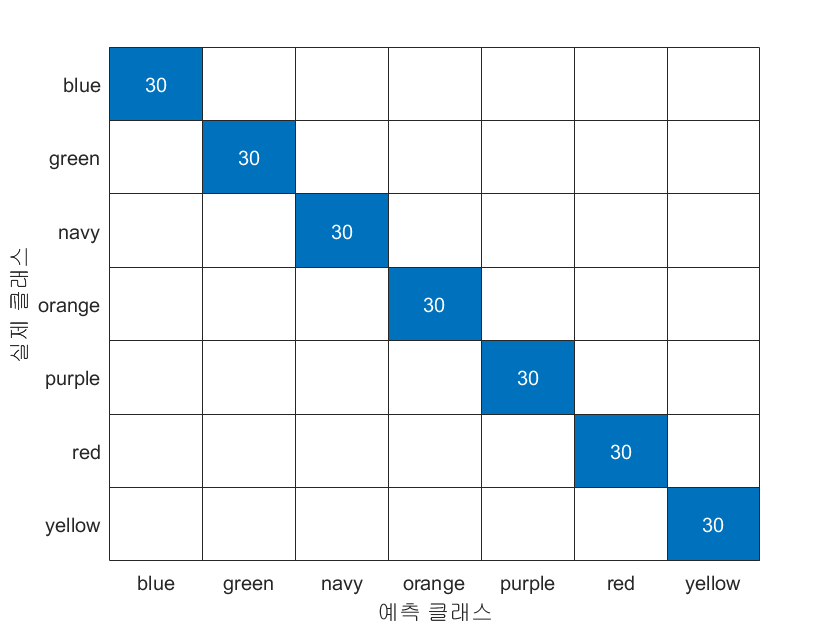

preds = classify(mynet, teds);

[m,order] = confusionmat(teLabel, preds);
figure
confusionchart(m, order)